# Day-2 (Functions, File I/O and data visualization)

## Functions

Functions allow us to modularize our code into reusable chucks, while also making it more readable. Let's continue with our max number finding problem Day-1. In order to find the max of different number lists, we had to iteratively the number list variable in our code. Using functions we can make the algorithm independent of the number list, and later on run any number list through the function. This is identical to the function idea in mathematics where we can define a function with a variable x ($f\left(x\right)=sin\left(x\right)$) and later on evaluate for a particular value x.

Here is an example of using a max_finder function (defined below) and multiple number lists. 

max_finder([49 46 63 62 25 14 8 62 35 36])

ans = 63

max_finder([841238 619645 209407 435618 832714 887185 164080 939827 179879 517613])

ans = 939827

max_finder([-630 -260 -298 -538 -176 -596 -23 -693 -791 -271])

ans = -23

Here is how one defines a function in matlab. The first line declares the input to the function (number_list in this example) and output from the function (max here). [The real defintion is below. All functions should be in the end of local scripts - matlab constraint].

% function [max] = max_finder(number_list)
% 
% max = number_list(1);
% 
% for curr_num = number_list
%     if (curr_num > max)
%         max = curr_num;
%     end 
% end
% 
% end

## First 100 prime numbers using functions

Try your own version of a prime number function (you will find the answer below in case you want to compare). To find the first hundred primes, we simply need to run the function for all numbers and store 100 primes.

prime_numbers = [];
curr_number = 2;
while(length(prime_numbers) <=100)
    if isnumberprime(curr_number)
        prime_numbers = [prime_numbers, curr_number];
    end
    curr_number = curr_number + 1;  
end
disp(prime_numbers)

  Columns 1 through 14

     2     3     5     7    11    13    17    19    23    29    31    37    41    43

  Columns 15 through 28

    47    53    59    61    67    71    73    79    83    89    97   101   103   107

  Columns 29 through 42

   109   113   127   131   137   139   149   151   157   163   167   173   179   181

  Columns 43 through 56

   191   193   197   199   211   223   227   229   233   239   241   251   257   263

  Columns 57 through 70

   269   271   277   281   283   293   307   311   313   317   331   337   347   349

  Columns 71 through 84

   353   359   367   373   379   383   389   397   401   409   419   421   431   433

  Columns 85 through 98

   439   443   449   457   461   463   467   479   487   491   499   503   509   521

  Columns 99 through 101

   523   541   547



## Recursive functions

Sometimes, you can rephrase a function for one value in terms of the function for another (generally lower) value. Such class of functions are called recursive functions. Think of the factorial computation. A factorial of n is the product of all integers from 1 to n. An alternative way of computing this is to define n! as a product of n and (n-1)!. This is the recursive definition of the factorial. Try to write a recursive function yourself (solution in the bottom). 

Another example is the fibonacci sequence, which is defined as the sum of the previous two fibonacci values. Again try it out yourself (solution in the bottom). 

Here is an example computations of the factorial and fibonacci function.

factorial_of(3)

ans = 6

factorial_of(5)

ans = 120

factorial_of(10)

ans = 3628800


fibonacci(1)

ans = 1

fibonacci(2)

ans = 1

fibonacci(3)

ans = 2

fibonacci(4)

ans = 3

fibonacci(5)

ans = 5


fprintf('%d, %d, %d, %d, %d, %d, %d, %d, %d, %d', fibonacci(1),...
    fibonacci(2),...
    fibonacci(3),...
    fibonacci(4),...
    fibonacci(5),...
    fibonacci(6),...
    fibonacci(7),...
    fibonacci(8),...
    fibonacci(9),...
    fibonacci(10));

1, 1, 2, 3, 5, 8, 13, 21, 34, 55

## Basic file I/O (input output)

Reading/Writing a file in MATLAB comprises of three steps:

- Opening a file - read mode (**r**), write mode (**w**) and the append mode (**a**) are typical modes used to open a file.

fid1 = fopen('../Lorem_Ipsum.txt','r'); 
fid2 = fopen('../Simple_sums.txt','w'); 
fid3 = fopen('../Lorem_Ipsum.txt','a');

        2.1  Reading a file

% Reading a line (there are different ways of doing this. Look this up if you need it. This is just an example).
disp(fgetl(fid1));

Lorem ipsum dolor sit amet, consectetuer adipiscing elit. Aenean commodo ligula eget dolor. 


% Reading the 10 haracters
disp(fread(fid1,10,'*char')');

Aenean mas


% Notice that matlab keeps track of the lines/characters read, and resumes after that. 
disp(ftell(fid1)); % Gives the current location 

   103



disp(fread(fid1,10,'*char')'); % Reads the next 10 characters

sa. 
Cum s


% You can move the tracked location using fseek
fseek(fid1, -10, 0); % This moves the tracked location back by 10 characters from origin (0).
disp(fread(fid1,10,'*char')'); % Reads the next 10 characters

sa. 
Cum s


% To read the whole data at once, simply use fscanf
disp(fscanf(fid1, '%s'));

ociisnatoquepenatibusetmagnisdisparturientmontes,nasceturridiculusmus.Donecquamfelis,ultriciesnec,pellentesqueeu,pretiumquis,sem.Nullaconsequatmassaquisenim.Donecpedejusto,fringillavel,aliquetnec,vulputateeget,arcu.Inenimjusto,rhoncusut,imperdieta,venenatisvitae,justo.Nullamdictumfeliseupedemollispretium.Integertincidunt.Crasdapibus.Vivamuselementumsempernisi.Aeneanvulputateeleifendtellus.Aeneanleoligula,porttitoreu,consequatvitae,eleifendac,enim.Aliquamloremante,dapibusin,viverraquis,feugiata,tellus.Phasellusviverranullautmetusvariuslaoreet.Quisquerutrum.Aeneanimperdiet.Etiamultriciesnisivelaugue.Curabiturullamcorperultriciesnisi.Namegetdui.Etiamrhoncus.Maecenastempus,tellusegetcondimentumrhoncus,semquamsemperlibero,sitametadipiscingsemnequesedipsum.Namquamnunc,blanditvel,luctuspulvinar,hendreritid,lorem.Maecenasnecodioetantetincidunttempus.Donecvitaesapienutliberovenenatisfaucibus.Nullamquisante.Etiamsitametorciegeterosfaucibustincidunt.Duisleo.Sedfringillamaurissitametnibh.Donecsoda

       2.2 Writing into a file

**Note that when you one a file in write mode, it erases the existing content. Open in append mode if you want to add more lines.**

% We use fprintf to write into files. 
fprintf(fid2, '%s %d.\n', 'two plus two equals', 4); % \n indicates a new line after the full stop
fprintf(fid2, '%s %d.\n', 'three plus three equals', 6); 

% This does not work in read mode
fprintf(fid1, '%s %d.\n', 'two plus two equals', 4); 
fprintf(fid1, '%s %d.\n', 'three plus three equals', 6); 

% Appending is similar to writing
fprintf(fid3, '%s %d.\n', 'two plus two equals', 4); 
fprintf(fid3, '%s %d.\n', 'three plus three equals', 6); 

        3. Closing a file

After reading/writing do not forget to close the file

fclose(fid1);
fclose(fid2);
fclose(fid3);

**Note that you can read and append on the same file (although this is not a good idea). **

Although it is useful to know the above basics of file I/O, we typically do not use this. This is because do this for every format type is time consuming. You can of course write functions for it and keep reusing it when every you need to read a file. MATLAB has done exactly that. There are already built in functions which reads different formats and converts it into matrixes or tables or other data structures. We can simply use this instead of writing our own function. It is however a good exercise to try this out yourself, as it helps you develop a general intution.

## Reading the iris dataset

If the data has a particular format, it is very easy to read it. Typically, we use functions like textscan to read every line of a text file, based on what we expect to find. The iris dataset for example has 4 columns of decimals and one string, each separated by a column (per line). This is how you read it.

fid = fopen('../iris.data');
data = textscan(fid, '%f %f %f %f %s','Delimiter',',') % 4 decimals and one string, separated (delimiter) by comma

data =     [150×1 double]    [150×1 double]    [150×1 double]    [150×1 double]    {150×1 cell}


fclose(fid);

Tables are a very useful data structure in MATLAB. We can assign row and column names, move them around, etc etc. It is slighly better than using a matrix for systematic datasets.

data_table = table(data{1},data{2},data{3},data{4},data{5}, 'VariableNames', {'sepal_length','sepal_width','petal_length','petal_width','plant_name'})

data_table =     sepal_length    sepal_width    petal_length    petal_width       plant_name    
    ____________    ___________    ____________    ___________    _________________

    5.1             3.5            1.4             0.2            'Iris-setosa'    
    4.9               3            1.4             0.2            'Iris-setosa'    
    4.7             3.2            1.3             0.2            'Iris-setosa'    
    4.6             3.1            1.5             0.2            'Iris-setosa'    
      5             3.6            1.4             0.2            'Iris-setosa'    
    5.4             3.9            1.7             0.4            'Iris-setosa'    
    4.6             3.4            1.4             0.3            'Iris-setosa'    
      5             3.4            1.5             0.2      

data_matrix = cell2mat(data(1:4)); % a matrix cannot contain strings so we have to ignore that

This is a slightly painful way of getting a table. Easiest way is to use a csv or xl file as they are easy to convert to tables. CSV or comma separated values is the most common way of storing data. Columns are separated by commas and the rows by a new line. The extension simply makes it easy for us to identify the type of data. However, different extensions may still be comma separated. The iris dataset is one such example. Although it has a .data extension, it is actually a csv - open and have a look at it (you can try renaming the extension to csv). 

The below two lines can replace the above hassle we went through, if we had the data in the right format with the right extension.

data_table = readtable('../iris.csv'); % rename .data as .csv
% Give column names
data_table.Properties.VariableNames = {'sepal_length','sepal_width','petal_length','petal_width','plant_name'};
data_table

data_table =     sepal_length    sepal_width    petal_length    petal_width       plant_name    
    ____________    ___________    ____________    ___________    _________________

    5.1             3.5            1.4             0.2            'Iris-setosa'    
    4.9               3            1.4             0.2            'Iris-setosa'    
    4.7             3.2            1.3             0.2            'Iris-setosa'    
    4.6             3.1            1.5             0.2            'Iris-setosa'    
      5             3.6            1.4             0.2            'Iris-setosa'    
    5.4             3.9            1.7             0.4            'Iris-setosa'    
    4.6             3.4            1.4             0.3            'Iris-setosa'    
      5             3.4            1.5             0.2      

## Tables and data visualization

Tables have many interesting properties. It can be perform basic plot using this. For example, if we need to plot sepal length vs sepal width, we can do this:

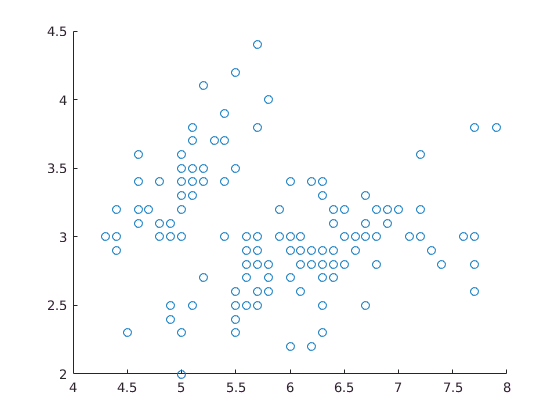

scatter(data_table.sepal_length, data_table.sepal_width);

We can color code it based on plant name. 

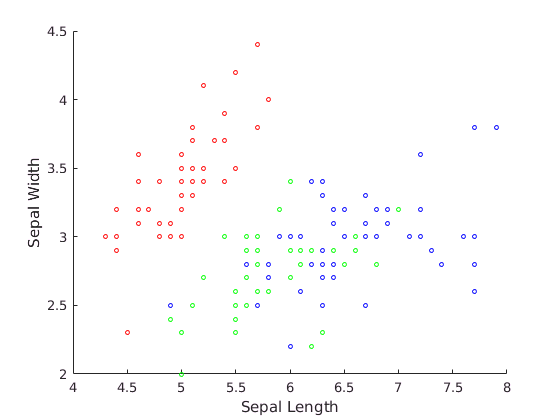

unique_names = unique(data_table.plant_name);
% Colors are 3 column vectors in matlab. It is a decimal form of RGB. Look up color specification in matlab
% red is [1,0,0] (only red). green is [0,1,0] and blue is [0,0,1].
plant_color = zeros(size(data_table.plant_name,1),3);   
% Let's give the first red color (make first column 1 for these)
indices_of_plant_1 = ismember(data_table.plant_name, unique_names{1});
plant_color(indices_of_plant_1,1) = 1;    % {} is required to keep the plant_color variable a cell. Replaces plant name cell with color cell.
% For the other two colors
plant_color(ismember(data_table.plant_name, unique_names{2}),2) = 1; %(make second column 1 - green)
plant_color(ismember(data_table.plant_name, unique_names{3}),3) = 1; %(make third column 1 - blue)

% We can add it to our table
data_table = [data_table, table(plant_color)];

% Plotting with color
scatter(data_table.sepal_length, data_table.sepal_width, 10, data_table.plant_color); % 10 indicates marker size
xlabel('Sepal Length'), ylabel('Sepal Width');

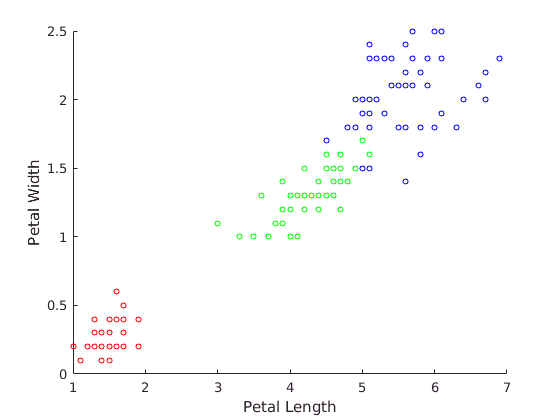

scatter(data_table.petal_length, data_table.petal_width, 15, data_table.plant_color); % 10 indicates marker size
xlabel('Petal Length'), ylabel('Petal Width');

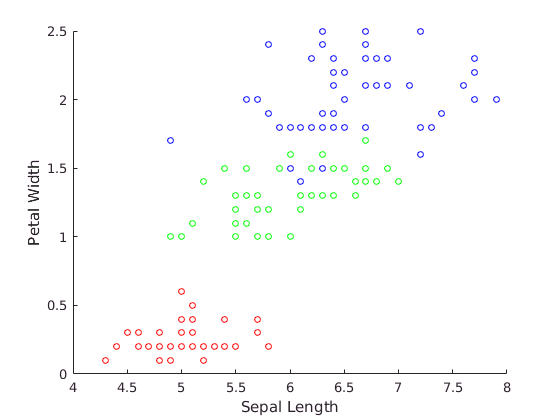

scatter(data_table.sepal_length, data_table.petal_width, 20, data_table.plant_color); % 10 indicates marker size
xlabel('Sepal Length'), ylabel('Petal Width');

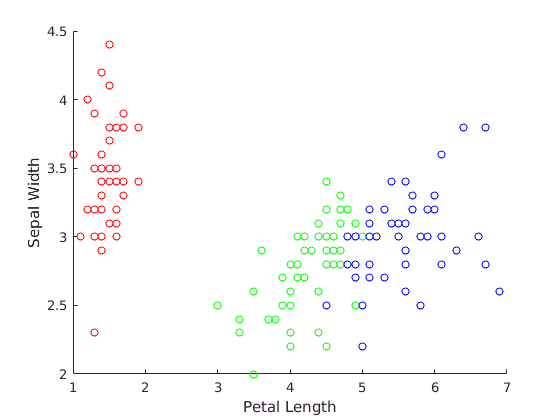

scatter(data_table.petal_length, data_table.sepal_width, 30, data_table.plant_color); % 10 indicates marker size
xlabel('Petal Length'), ylabel('Sepal Width');

Play around with the data set more. Look at sepal length-width ratio and add it to the table. Do the same with petals. Plot them with different color based on species

# Functions (solutions)

## Max finder function

function [max] = max_finder(number_list)

max = number_list(1);

for curr_num = number_list
    if (curr_num > max)
        max = curr_num;
    end 
end

end

## Prime number function

function [prime] = isnumberprime(number)
    % This function outputs prime=true when the number is prime, and prime=false when it is not prime.
    
    divisors = 2:number-1;
    
    % assume prime
    prime = true;    

    for curr_divisor = divisors
        if mod(number, curr_divisor) == 0
            prime = false;
            break;
        end
    end    
    
end

## Factorial (recursive) function

function [output] = factorial_of(number)
    
    if number == 1
        output = 1;
    else
        output = number * factorial_of(number - 1);
    end    
    
end

## Fibonacci (recursive) function

function [output] = fibonacci(number)
    
    if number == 1
        output = 1;
    elseif number == 2
        output = 1;
    else
        output = fibonacci(number - 1) + fibonacci(number - 2);
    end        
    
end
